# Numerical differentiation

Create the interval where we want to differentiate our function f.

h  =  1; % Step length

x0 =  0; % First value
xn = 10; % Last value

x = x0:h:xn;

Calculate the numerical derivate df at points x using step length h and naïve forward differentiation. First lets differentiate


$$f\left(x\right)=x$$


using a naïve approach where we define


$$\frac{\text{d}}{\text{d}x}f\left(x\right)\approx \frac{f\left(x+h\right)-f\left(x\right)}{h}=D_+ f\left(x\right)$$


as forward differentiation

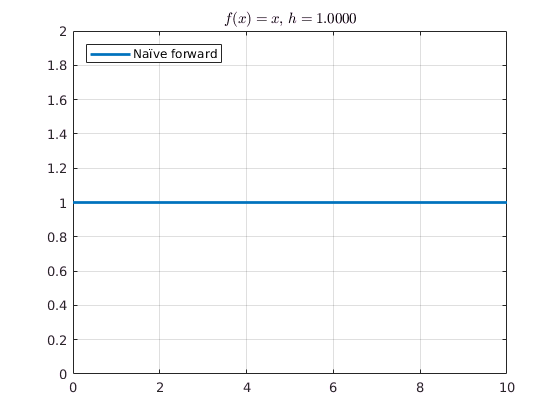

f = @(x) x;
df = dForward(f(x),h);
plot(x,df,'LineWidth',2);
title(sprintf('$$f(x)=x $$, $$h = %4.4f$$',h),'interpreter','latex');
legend('Naïve forward','Location','NorthWest');
grid on;

Notice that we can't calculte the numerical derivate at the endpoint since we don't have any information beyond the last point.

Next we want to differentiate


$$f\left(x\right)=x^2$$


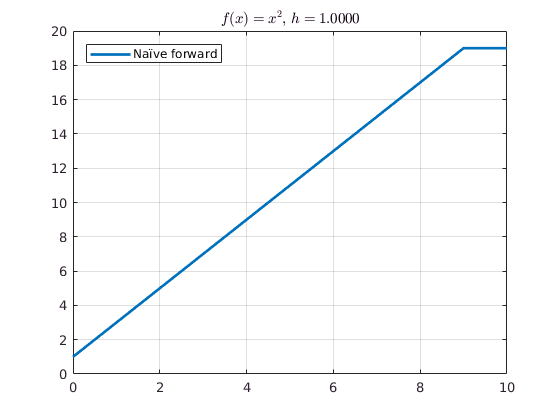

f = @(x) x.^2;
df = dForward(f(x),h);
plot(x,df,'LineWidth',2);
title(sprintf('$$f(x)=x^2$$, $$h = %4.4f$$',h),'interpreter','latex');
legend('Naïve forward','Location','NorthWest');
grid on;

Note that we get the wrong answer, but a smaller $h$ valvue will give us a more accurate result.

We can also look at the backward differentiation defined as


$$D_- f\left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h},$$


and compare this with forward differentiation.

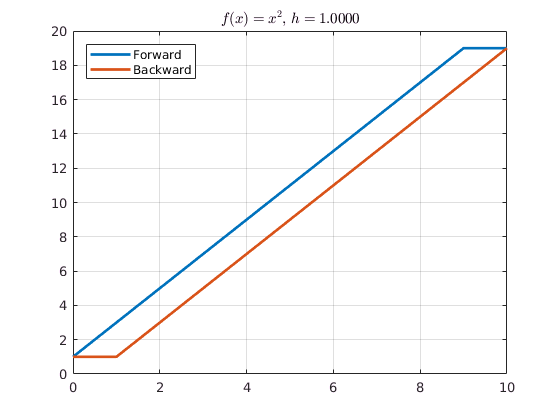

dpluss_f = dForward(f(x),h);
dminus_f = dBackward(f(x),h);
plot(x,dpluss_f,x,dminus_f,'LineWidth',2);
title(sprintf('$$f(x)=x^2$$, $$h = %4.4f$$',h),'interpreter','latex');
legend('Forward','Backward','Location','NorthWest');
grid on;

By Taylor expansion we have


$$f\left(x+h\right)=f\left(x\right)+h\cdot f^{\left(1\right)} \left(x\right)+\frac{h^2 }{2!}f^{\left(2\right)} \left(x\right)+\frac{h^3 }{3!}f^{\left(3\right)} \left(x\right)+\cdots$$



$$f\left(x-h\right)=f\left(x\right)-h\cdot f^{\left(1\right)} \left(x\right)+\frac{h^2 }{2!}f^{\left(2\right)} \left(x\right)-\frac{h^3 }{3!}f^{\left(3\right)} \left(x\right)+\cdots$$


Subtracting the first equation from the second yields


$$f\left(x+h\right)-f\left(x-h\right)=2{h\cdot f}^{\left(1\right)} \left(x\right)+\frac{2h^3 }{3!}f^{\left(3\right)} \left(x\right)\ldotp$$


With some rearranging we get 


$$\frac{\text{d}}{\text{d}x}f\left(x\right)=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}+O\left(h^2 \right)\ldotp$$


Compairing this with the forward and backward differentiation we get

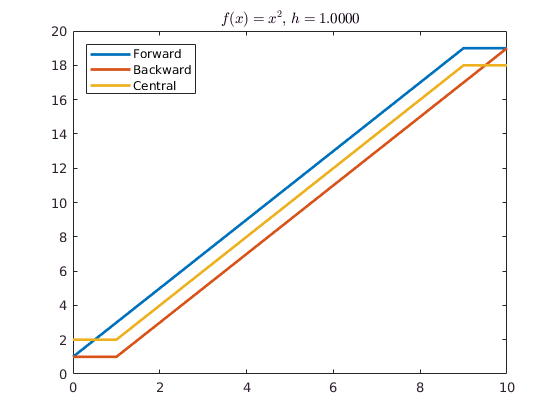

dcenter_f = dCentral(f(x),h);
plot(x,dpluss_f,x,dminus_f,x,dcenter_f,'LineWidth',2);
title(sprintf('$$f(x)=x^2$$, $$h = %4.4f$$',h),'interpreter','latex');
legend('Forward','Backward','Central','Location','NorthWest');

We can get a better estimate by including more datapoints. By Taylor expanding$f\left(x+2h\right)$and$f\left(x-2h\right)$we can calculate


$$8\left\lbrack f\left(x+h\right)-f\left(x-h\right)\right\rbrack -\left\lbrack f\left(x+2h\right)-f\left(x-2h\right)\right\rbrack =12h\cdot f^{\left(1\right)} \left(x\right)-\frac{48h^5 }{5!}f^{\left(5\right)} \left(x\right)+\cdots$$


which gives us


$$\frac{\text{d}}{\text{d}x}f\left(x\right)=\frac{f\left(x-2h\right)-8f\left(x-h\right)+8f\left(x+h\right)-f\left(x+2h\right)}{12h}+O\left(h^4 \right)\ldotp$$


Compare the four methods on 


$$f\left(x\right)=x^4$$


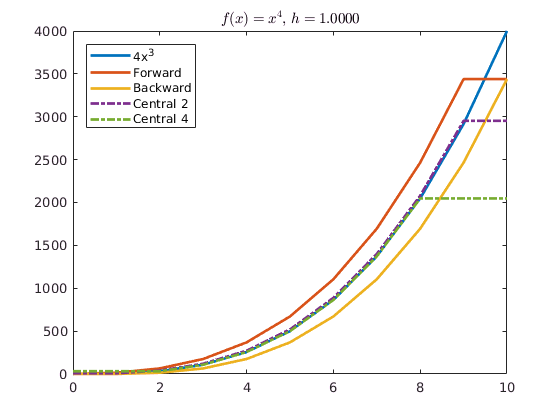

f = @(x) x.^4;

h  =  1; % Step length

x0 =  0; % First value
xn = 10; % Last value

x = x0:h:xn;

dforw = dForward(f(x),h);
dminu = dBackward(f(x),h);
dcen2 = dCentral(f(x),h);
dcen4 = dCentral4(f(x),h);

plot(x,4.*x.^3,...
     x,dforw,...
     x,dminu,...
     x,dcen2,'-.',...
     x,dcen4,'-.',...
     'LineWidth',2);
title(sprintf('$$f(x)=x^4$$, $$h = %4.4f$$',h),'interpreter','latex');
legend('4x^3','Forward','Backward','Central 2','Central 4','Location','NorthWest');   

## Error analysis

It can be shown that the 2nd order central differentiation approximation has the error bound


$$|E(f,h)| \leq \frac{\epsilon}{h} + \frac{M h^2}{6}$$


where $\epsilon$is the floating point operation error and $M=\underset{x-h\le x\le x+h}{\mathrm{min}} |f^{\left(3\right)} \left(x\right)|$. We can then estimate the best $h$ by differentiating $|E(f,h)|$ w.r.t. $h$ and setting it equal to zero solving for $h$


$$h = \left( \frac{3\epsilon}{M} \right)^{(1/3)}\right).$$


Looking at 


$$f(x) = cos(x)$$


we can estimate the optimal step length around $x_0 = 0.9$ when we assume that $\epsilon = 5\cdot 10^{-10}$.

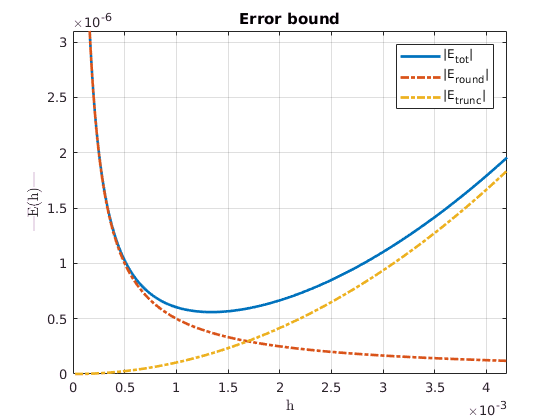

eps = 5e-10;
x = 0.9;
h = 2e-5:1e-5:2e-2;
M = zeros(1,length(h));
M(:) = abs(max(cos(x+h), cos(x-h)));

error = eps./h + M.*h.^2/6;

plot(h,error,h,eps./h,'-.',h,M.*h.^2/6,'-.','LineWidth',2);
title('Error bound');
xlabel('h','interpreter','latex');
ylabel('|E(h)|','interpreter','latex');
legend('|E_{tot}|','|E_{round}|','|E_{trunc}|');
grid on;

xlim([0.0000 0.0042])
ylim([0.0000000 0.0000031])


[mErr, iErr] = min(error);
hOpt = ((3*eps)/max(M(:)))^(1/3);
hErr = eps/hOpt + (max(M(:))*hOpt*hOpt)/6;

fprintf('Found     optimal h: %4.3e with |E| <= %4.3e',h(iErr), mErr);

Found     optimal h: 1.340e-03 with |E| <= 5.595e-07

fprintf('Estimated optimal h: %4.3e with |E| <= %4.3e',hOpt,hErr);

Estimated optimal h: 1.330e-03 with |E| <= 5.638e-07

## Second derivative

We can estimate the second derivative in a similar manner. By adding the Taylor expansion of $f(x+h)$ and $f(x-h)$ instead of subtracting them, we get


$$\frac{{\text{d}}^2 }{\text{d}x^2 }f\left(x\right)=\frac{f\left(x-h\right)-2f\left(x\right)+f\left(x+h\right)}{h^2 }+O\left(h^2 \right)\ldotp$$


Alternatively we can apply the first derivative twice. Looking at 


$$f(x) = cos(x)$$


we can study the accuracy of these methods since we know that 


$$\frac{{\text{d}}^2 }{\text{d}x^2 }f\left(x\right)=-\mathrm{cos}\left(x\right)$$


f = @(x) cos(x);

h  = .5; % Step length
x0 =  0; % First value
xn = 10; % Last value
x = x0:h:xn;

Using First derivatives twice

% Central
dc   = dCentral(f(x),h);
dcdc  = dCentral(dc,h);
% Forward then backward
df   = dForward(f(x),h);
dbdf = dBackward(df,h);

Using the second derivative approximation directly

ddc = ddCentral(f(x),h); 

Plotting the derivatives with error

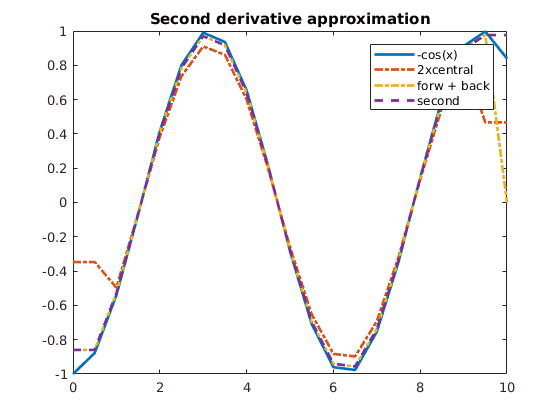

plot(x,-cos(x),x,dcdc,'-.',x,dbdf,'-.',x,ddc,'--','LineWidth',2);
legend('-cos(x)','2xcentral','forw + back','second');
title('Second derivative approximation');

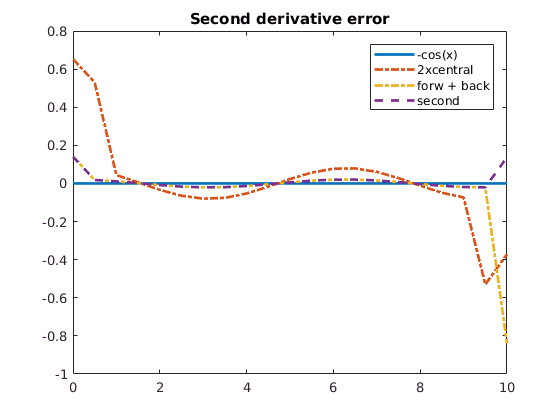


plot(x,-cos(x)+cos(x),x,dcdc+cos(x),'-.',x,dbdf+cos(x),'-.',x,ddc+cos(x),'--','LineWidth',2);
legend('-cos(x)','2xcentral','forw + back','second');
title('Second derivative error');

## Function definitions

1st order forward differentiator

function df = dForward(f,h)
    n  = length(f);
    df = zeros(1,n);
    df(1:n-1) = (f(2:n)-f(1:n-1))/h;
    % We can't compute the last point so we copy the next last.
    df(n) = df(n-1);
end

1st order backward differentiator

function df = dBackward(f,h)
    n  = length(f);
    df = zeros(1,n);
    df(2:n) = (f(2:n)-f(1:n-1))/h;
    % We can't compute the first point so we copy the second.
    df(1) = df(2);
end

2nd order central differentiator

function df = dCentral(f,h)
    n  = length(f);
    df = zeros(1,n);
    df(2:n-1) = (f(3:n)-f(1:n-2))/(2*h);
    % We can't compute the endpoints so we copy the next point.
    df(1) = df(2);
    df(n) = df(n-1);
end

4th order central differentiator

function df = dCentral4(f,h)
    n  = length(f);
    df = zeros(1,n);
    df(3:n-2) = (f(1:n-4)-8*f(2:n-3)+8*(f(4:n-1))-f(5:n))/(12*h);
    df(2)   = df(3);
    df(1)   = df(2);
    df(n-1) = df(n-2);
    df(n)   = df(n-1);
end

2nd order central 2nd order differentiator

function ddf = ddCentral(f,h)
    n   = length(f);
    ddf = zeros(1,n);
    ddf(2:n-1) = (f(1:n-2)-2*f(2:n-1)+f(3:n))./(h*h);
    ddf(1) = ddf(2);
    ddf(n) = ddf(n-1);
end